# Pickleball and Tennis - A time for peace

Words here motivating.  Images too.

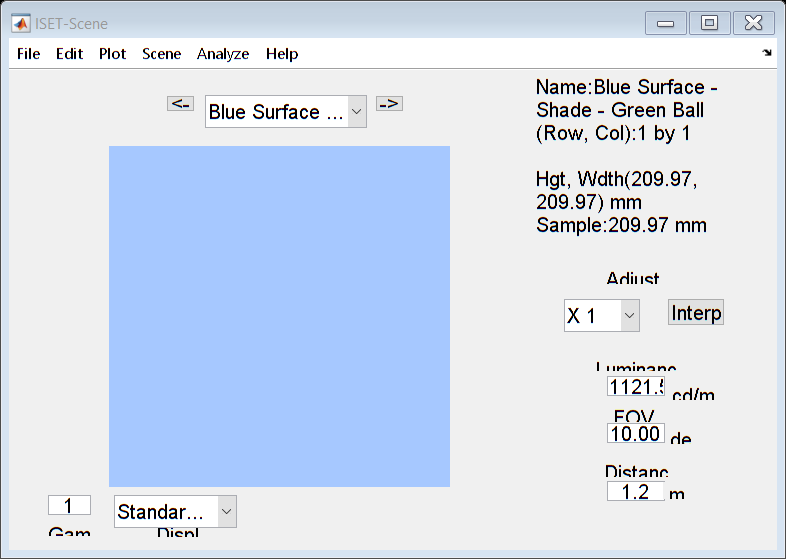

wavelength = 400:10:700;

scene = sceneCreate;
%scene = sceneSet(scene,'wave', wavelength);

illuminant = ieReadSpectra('spd-2022-11-13_blue_line_on_green_surface_in_shade_white_calibration.mat',wavelength);
plotRadiance
scene = sceneSet(scene,'illuminantenergy', illuminant);

scene = sceneSet(scene,'name', 'Blue Surface - Shade - Green Ball');
spectral_radiance = zeros(1,1,length(wavelength));

% The original file here was the same as the illuminant file
spectral_radiance(:,:,:) = ieReadSpectra('spd-2022-11-13_blue_line_on_green_surface_in_shade_white_calibration.mat',wavelength);

% Maybe read some of these files.  I can help you create an image from
% the individual radiance files.  There are examples of how to do this
% in sceneCreate.
%
% spectral_radiance(:,:,:) = ieReadSpectra('spd-2022-11-13_white_line_on_greenblue_surface_in_shade.mat',wavelength);

scene = sceneSet(scene,'energy', spectral_radiance);
sceneWindow(scene);